# Hunt for a sensible LQI solution - part 2

Load the Linearised quadcopter+pendulum model

%load('bh_results_HUNT_part_1_1to1e5.mat')
load('bh_results_HUNT_part_1.mat')
whos

  Name           Size                    Bytes  Class     Attributes

  res_array      1x500000            465425984  struct              



Recall the fieldnames:

res_array(1)

ans = struct with fields:
            tf_is_good: 0
                     K: []
                     p: []
    tf_all_inside_unit: 0
               p_first: 0
                  K_av: 0
                   g_Q: 0
                   g_R: 0


Apply "filter" settings:

ind         = [res_array.tf_is_good] & [res_array.tf_all_inside_unit] ;
WORK_list   = res_array(ind);

whos WORK_list

  Name           Size            Bytes  Class     Attributes

  WORK_list      1x36            70496  struct              



Look for the closest to our CONFIRMED design

tmp_vec =  zeros( size(length(WORK_list) ) );

for kk=1:length(WORK_list)
    
    tmp_vec(kk)  = mean(abs(WORK_list(kk).K), 'all');    
end

[tmp_vec, ind] = sort(tmp_vec);
WORK_list = WORK_list(ind);
whos WORK_list

  Name           Size            Bytes  Class     Attributes

  WORK_list      1x36            70496  struct              



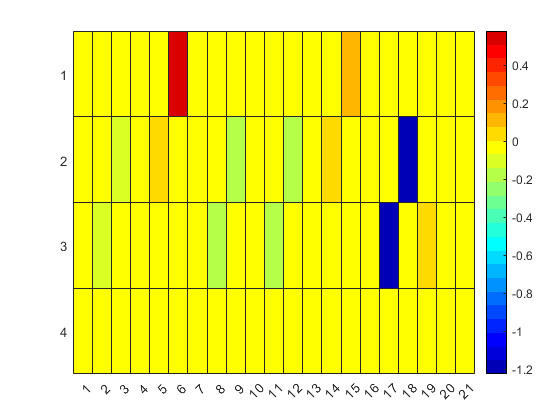

kk=1;


w = WORK_list(kk);

figure;  heatmap(w.K,'Colormap',jet(25));

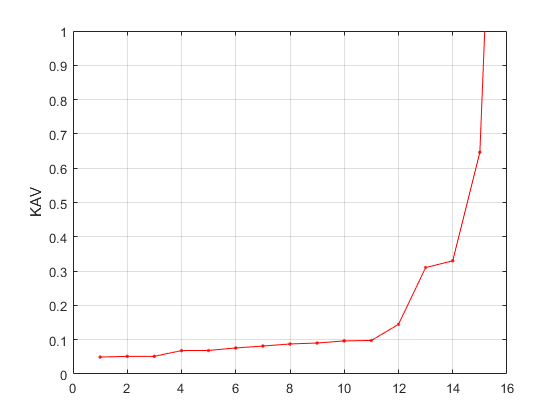

YLIM_VAL = 1;
figure;
plot(tmp_vec,'-r.'); grid('on');
ylabel('KAV');
ylim([0, YLIM_VAL])

And save this list

tmp_ind = tmp_vec < 1;
WORK_list = WORK_list(tmp_ind);

whos WORK_list

  Name           Size            Bytes  Class     Attributes

  WORK_list      1x15            29694  struct              




save bh_candidate_K_laws WORK_list

w.p

ans =    1.0000 + 0.0000i
   1.0000 - 0.0000i
   1.0000 + 0.0000i
   1.0000 - 0.0000i
   0.9998 + 0.0033i
   0.9998 - 0.0033i
   0.9998 + 0.0033i
   0.9998 - 0.0033i
   0.9995 + 0.0005i
   0.9995 - 0.0005i
